usage: teamwork for week 13

author: 黄哲昊 毛晨光 鲁潇阳

date: 2020.5.30

clear all; close all; clc

**1. Leonard Euler和Colin Maclaurin在1735年左右独立发现的Euler-Maclaurin公式可以说明采用复合梯形公式， 在**等间距节点**对**周期函数**积分时所能达到的精度远比**$$O(h^2)$$**要高。 **

**   Euler-Maclaurin定理： 如果**$$f\in C^{2n}[a,b]$$**, **$$T_h$$**是对**$$\displaystyle\int_a^b f(x)dx$$**的复合梯形法则的计算结果， 则**

   
$$
   T_h-\int_a^b f(x)dx =\frac{h^2}{12}[f^\prime(b)-f^\prime(a)]-\frac{h^4}{720}[f^{(3)}(b)-f^{(3)}(a)]\\
    +\frac{h^6}{30,240}[f^{(5)}(b)-f^{(5)}(a)]-\cdots\\
     + (-1)^{n-2}\frac{b_{2n-2}}{(2n-2)!}h^{2n-2}[f^{(2n-1)}(b)-f^{(2n-1)}(a)]\\
     + (-1)^{n-1}\frac{b_{2n}}{（2n）!}h^{2n}f^{(2n)}(\xi), \quad \xi\in[a,b]\\
$$


**    公式中的**$$(-1)^{j-1}b_{2j}$$**称为Bernoulli数。**

**    这样如果**$$f$$**是周期是**$$b-a$$**或**$$\frac{b-a}{m}$$** (**$$m$$**是正整数)的周期函数， 与积分从何处开始无关， 上式的所有项除了最后一项都是零。 而且如果**$$f$$**无穷可微， **$$n$$**能够取到任意大， 梯形法则的误差将比**$$h$$**的任何幂次减小得都快， 这样得收敛速度称为超代数收敛 (这种超代数收敛并不唯一针对复合梯形法则， 其他方法包括高斯积分公式也可能， 甚至对非周期光滑函数超代数收敛)。**

**    请在等间距节点上用复合梯形法则计算**

    
$$$$
    \int_1^{1+4\pi}e^{\sin x}dx
    $$ $$


**    比较步长**$$h=\pi, \pi/2, \pi/4, \pi/8,\pi/16$$**的结果， 检验上述说法。**

解：

clear all; close all; clc
f_1 = @(x) exp(sin(x));
I_1_check = integral(f_1, 1, 1+4*pi);
fprintf("积分的真实值为：%f", I_1_check)

积分的真实值为：15.909853

T_1 = zeros(5, 1);
for i = 1:5
    n = 2^(i+1);
    T_1(i) = TrapComp(f_1, 1, 1+4*pi, n);
end
E_1 = T_1 - I_1_check;
fprintf("分段数\t h \t T_h \t 误差")

分段数	 h 	 T_h 	 误差

for i = 1:5
    fprintf("%d \t PI/%d \t %f \t %f\n", 2^(i+1), 2^(i-1), T_1(i), E_1(i))
end

4 	 PI/1 	 17.284118 	 1.374265
8 	 PI/2 	 15.864888 	 -0.044965
16 	 PI/4 	 15.909853 	 -0.000000
32 	 PI/8 	 15.909853 	 0.000000
64 	 PI/16 	 15.909853 	 -0.000000


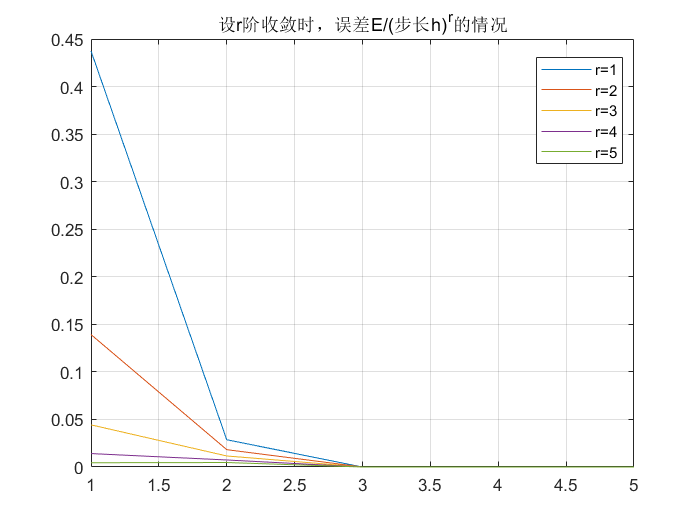


% 计算收敛阶数
R_1_1 = zeros(5, 5);
for i = 1:5
    R_1_1(i, :) = abs(E_1(1:5))'./(pi./2.^(0:4)).^(i);
end
plot(1:5, R_1_1(1, :))
hold on
plot(1:5, R_1_1(2, :))
plot(1:5, R_1_1(3, :))
plot(1:5, R_1_1(4, :))
plot(1:5, R_1_1(5, :))
hold off
legend("r=1","r=2","r=3","r=4","r=5",'Location',"best")
title("设r阶收敛时，误差E/(步长h)^r的情况")
grid on

从图中可以看到随着步长h的减小，复合梯形法则计算的积分值与真实值之间的误差与步长h的r阶次方的比值，仍然趋向于0，说明5阶的情况下迭代速度超过h的最高5阶幂次，是超代数收敛。

**2. 求对所有形式是**$$f(x)=ae^x+b\cos\left(\frac{\pi x}{2}\right)$$**的函数都准确的公式**


$$   $$
   \int_0^1 f(x)dx\approx A_0f(0)+A_1f(1)
   $$$$


  $ $f(x)$$**的表达式中的**$$a$$**和**$$b$$**是任意常数。**

解：


$$对f(x)积分得\\
\int^1_0ae^x = a \cdot (e-1)\\
\int^1_0bcos(\frac \pi 2x) = b\cdot \frac 2 \pi \cdot sin(\frac \pi 2)=b\cdot\frac2 \pi\\
又因为f(0)=a+b;f(1)=a\cdot e \\
\therefore \int_0^1 f(x)dx = A_0f(0)+A_1f(1)=A_0(a+b)+A_1\cdot e\cdot a = (e-1)\cdot a + \frac 2 \pi b\\
解方程即为 \\
\begin{cases}
A_0 =\frac 2 \pi \\
A_1= 1-\frac{1+\frac2 {\pi}}{e}
\end{cases}\\
\therefore \int_0^1 f(x)dx= \frac 2 \pi f(0)+(1-\frac{1+\frac2 {\pi}}{e})f(1)
$$


**3. 已知"嫦娥一号"卫星的近地点距离**$$h_1=200$$**km, 远地点距离**$$h_2=51000$$**km, 地球半径**$$R=6378$$**km. 求**

**    (1) 椭圆轨道的长半轴**$$a=?$$**, 短半轴**$$b=?$$    

**    提示：如图所示**$$a^2=b^2+c^2$$**.      **

**    (2) 分别利用5点和10点高斯积分方法计算椭圆轨道的长度**$L$**, **


$$    $$
    L=4\int_0^{\pi/2}\sqrt{x^2+y^2}d\theta=4\int_0^{\pi/2}\sqrt{a^2\cos^2\theta+b^2\sin^2\theta}d\theta
    $$$$


**    (3) 与Matlab内置函数`integral`的计算结果比较， 高斯积分方法计算值的相对误差是多少？**

解：

（1）

clear all; close all; clc
format long
h_1 = 200;
h_2 = 51000;
R = 6378;
% 长半轴
a_3 = (h_1 + h_2 + 2*R)/2

a_3 =        31978


c_3 = h_2 + R  - a_3;
% 短半轴
b_3 = sqrt(a_3^2 - c_3^2)

b_3 =      1.942762167636584e+04


椭圆轨道的长半轴$a=31978$km，短半轴$b=19427.76$km。

（2）

使用勒让德多项式的解作为高斯积分的取点

f_3 = @(x) 4*sqrt(a_3^2.*cos(x).^2 + b_3^2.*sin(x).^2);
[I_3_5, root_3_5, weight_3_5] = GaussL(f_3, 0, pi/2, 5) % 5点高斯积分

I_3_5 =      1.639108808646213e+05


root_3_5 =   -0.906179845938664  -0.538469310105683  -0.000000000000000   0.538469310105683   0.906179845938664


weight_3_5 =    0.236926885056189
   0.478628670499368
   0.568888888888887
   0.478628670499367
   0.236926885056189


[I_3_10, root_3_10, weight_3_10] = GaussL(f_3, 0, pi/2, 10) % 10点高斯积分

I_3_10 =      1.639111645064743e+05


root_3_10 =   -0.973906528517172  -0.865063366688984  -0.679409568299024  -0.433395394129248  -0.148874338981631   0.148874338981631   0.433395394129247   0.679409568299024   0.865063366688984   0.973906528517172


weight_3_10 =    0.066671344308687
   0.149451349150585
   0.219086362515977
   0.269266719309997
   0.295524224714759
   0.295524224714741
   0.269266719310010
   0.219086362515970
   0.149451349150587
   0.066671344308687


通过5点高斯积分得到的$L=1.6391\times 10^5km$，通过10点高斯积分得到的$L=1.6391\times 10^5km$。

（3）

I_3_check = integral(f_3, 0, pi/2)

I_3_check =      1.639111645052142e+05


E_3_5 = abs(I_3_check - I_3_5)/I_3_check

E_3_5 =      1.730453162396780e-06


E_3_10 = abs(I_3_check - I_3_10)/I_3_check

E_3_10 =      7.687397886702232e-12


通过与Matlab内置函数‘integral’比较，5点高斯积分的相对误差为$1.7304\times 10^{-6}$，10点高斯积分的相对误差为$7.6872\times10^{-12}$

**4. 利用2点高斯积分计算二重积分**


$$   $$
   I =\int\int_K(2-x-2y) dxdy 
   $$$$


**   其中**$$K$$**是以下三点定义的三角形: **$$(0,0)$$**, **$$(1,1/2)$$**和**$$(0,1)$$**.  **

**   提示：    **

**   (a) 当**$$h(x)\leq y\leq g(x)$$**, 可设**


$$   $$
   y= [g(x)-h(x)]z+h(x)
   $$$$


**   则**$$z\in[0,1]$$**.   **

**   (b) 此题的精确解为1/3.**

解：

方法一

首先画出积分区域

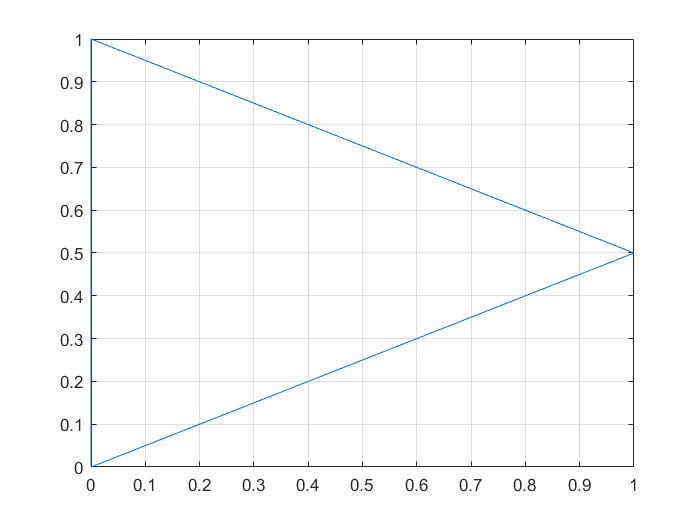

clear all; close all; clc
x_4_plot = [0, 1, 0, 0];
y_4_plot = [0, 0.5, 1, 0];
plot(x_4_plot, y_4_plot);
grid on

可以得到$0 \le x\le1,\frac12x\le y \le1-\frac12x$

f_4 = @(x, y) 2-x-2*y;
b_4 = 1; a_4 = 0;
root_4 = [-1/sqrt(3), 1/sqrt(3)];
weight_4 = [1, 1];
x_4 = (b_4 - a_4)/2*root_4+(b_4 + a_4)/2;
X_4 = repmat(x_4, 2, 1)

X_4 =    0.211324865405187   0.788675134594813
   0.211324865405187   0.788675134594813


h = @(x) 0.5*x;
g = @(x) 1-0.5*x;

令$Y=\pmatrix{(g(X_4(1))-h(X_4(1)))z_1+h(X_4(1)) & (g(X_4(2))-h(X_4(2)))z_1+h(X_4(2)) \cr 
(g(X_4(1))-h(X_4(1)))z_2+h(X_4(1)) & (g(X_4(2))-h(X_4(2)))z_2+h(X_4(2)) }=
\pmatrix{z_1 & 1 \cr z_2 & 1}
\pmatrix{g(X_4(1)-h(X_4(1)) & g(X_4(2)-h(X_4(2))\cr
 h(X_4(1)) & h(X_4(2))}=
\pmatrix{X_4(1) & 1 \cr X_4(2) & 1}
\pmatrix{g(X_4(1))-h(X_4(1)) & g(X_4(2))-h(X_4(2))\cr
 h(X_4(1)) & h(X_4(2))}$

Y_4 = [x_4',ones(2, 1)]*[g(x_4) - h(x_4); h(x_4)];
Z_4 = f_4(X_4, Y_4);
I_4_1 = (b_4 - a_4)*(g(x_4) - h(x_4))/4.*weight_4*Z_4*weight_4'

I_4_1 =    0.333333333333333


方法二

y=(1-x)z+0.5x 带入到func中


$$I=\int \int _ { K } ( 2 - x - 2 y ) d x d y
=\int _ { 0 } ^ { 1 } \int _ { 0 } ^ { 1 } [ 2 - x - 2 ( 1 - x ) z - x ] ( 1 - x )dxdz$$


func = @(x,z) (2-x-2*(1-x).*z-x).*(1-x);
b1 = 1; a1 = 0;% x的取值范围
b2 = 1; a2 = 0;% z的取值范围
root2 = [-sqrt(1/3) sqrt(1/3)]';
weight2 = [1 1];
x2 = (b1 - a1)/2*root2 + (b1 + a1)/2;
y2 = (b2 - a2)/2*root2 + (b2 + a2)/2;
[X,Y] = meshgrid(x2,y2);
Z = func(X,Y);
I_4_2 = (b2 - a2)*(b1 - a1)/4*weight2*Z*weight2'

I_4_2 =    0.333333333333333


验证得到的结果为1/3。

**5. 利用5点高斯积分计算三重积分**


$$   $$
   I=\int_0^1\int_0^1\int_0^1 \frac{1}{\sqrt{x+y+z}}dxdydz
   $$$$


解：

clear all; close all; clc
f_5 = @(x, y, z) 1./sqrt(x + y + z);
b_5 = 1; a_5 = 0;
% 计算五点高斯积分的权重和取点
rm = sqrt(5 - 2*sqrt(10./7))/3;
rp = sqrt(5 + 2*sqrt(10./7))/3;
root_5 = [-rp -rm 0 rm rp]';
wm = (322. + 13.*sqrt(70))/900;
wp = (322. - 13.*sqrt(70))/900;
weight_5 = [wp wm 128./225 wm wp];
% 计算网格
x_5 = (b_5 - a_5)/2*root_5 + (b_5 + a_5)/2;
y_5 = (b_5 - a_5)/2*root_5 + (b_5 + a_5)/2;
z_5 = (b_5 - a_5)/2*root_5 + (b_5 + a_5)/2;
[X_5, Y_5, Z_5] = meshgrid(x_5, y_5, z_5);
F_5 = f_5(X_5, Y_5, Z_5);
% 方法1
% 运用矩阵计算
I_5_1 = ((b_5 - a_5)/2)^3*weight_5*sum(F_5.*reshape(weight_5, 1, 1, 5), 3)*weight_5'

I_5_1 = 0.8628

%方法2
% 或者使用循环进行求和运算
I_5_2 = 0;
for i = 1:5
    for j = 1:5
        for k = 1:5
            I_5_2 = I_5_2 + weight_5(i)*weight_5(j)*weight_5(k)*F_5(i,j,k);
        end
    end
end
I_5_2 = I_5_2*((b_5-a_5)/2)^3

I_5_2 = 0.8628

% 求解精确值
I_5_check = integral3(f_5, 0, 1, 0, 1, 0 ,1)

I_5_check = 0.8629

% 计算相对误差
E_5 = abs(I_5_check - I_5_1)/I_5_check

E_5 = 5.7758e-05

5点高斯积分计算得到的积分值为0.86283，真实值为0.86288，两者的相对误差为$5.7758\times 10^{-5}$

**6. 利用表格中的数据求在**$$x=3.6$$**处的二阶微商**

**   | **$$x_k$$** | **$$y_k$ $** |**

**   | 3     | 0.4817 |**

**   | 3.3   | 0.9070 |**

**   | 3.6   | 1.4496 |**

**   | 3.9   | 2.1287 |**

**(1) 选择合适的3点作二阶多项式插值后求解；**

**(2) 应用matlab内置函数`diff'求解。**

解：

（1）

首先用散点图的方式观察数据：

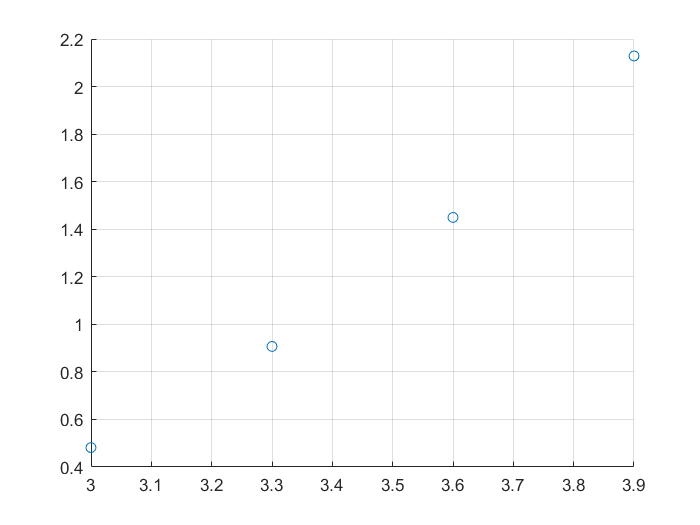

clear all; close all; clc
x_6 = [3, 3.3, 3.6, 3.9];
y_6 = [0.4817, 0.9070, 1.4496, 2.1287];
scatter(x_6, y_6)
grid on

由于求$$x=3.6$$处的二阶微商，故采用中间值为3.6的3.3、3.6、3.9三点进行二阶多项式插值。

p_6 = polyfit(x_6(2:end), y_6(2:end), 2);
df2_6_poly = 2*p_6(1)

df2_6_poly =    1.516666666666691


由二阶多项式插值得到的二阶微商为1.5167。

（2）

h_6 = 0.3;
delty_6 = diff(y_6);
df1_6_diff = delty_6./h_6; % 一阶差分
delt2y_6 = diff(df1_6_diff);
df2_6_diff = delt2y_6./h_6 % 二阶差分

df2_6_diff =    1.303333333333333   1.516666666666665


使用diff得到的二阶微商也为1.5167。

**7. 以下表格记录了1960年至2010年之间每隔10年所统计的加拿大人口总数，**

**    | 年 **$$t$$**    | 人口, **$$p$$** (百万) |**

**    | 1960   |     17.9         |**

**    | 1970   |     21.3         |**

**    | 1980   |     24.6         |**

**    | 1990   |     27.8         |**

**    | 2000   |     30.8         |**

**    | 2010   |     34.1         |**

**(1) 利用三点反向差分公式计算2010年人口增长率。**

**(2) 利用(1)的结果， 以及两点中心差分公式， 预测2020年的人口总数。**

解：

（1）

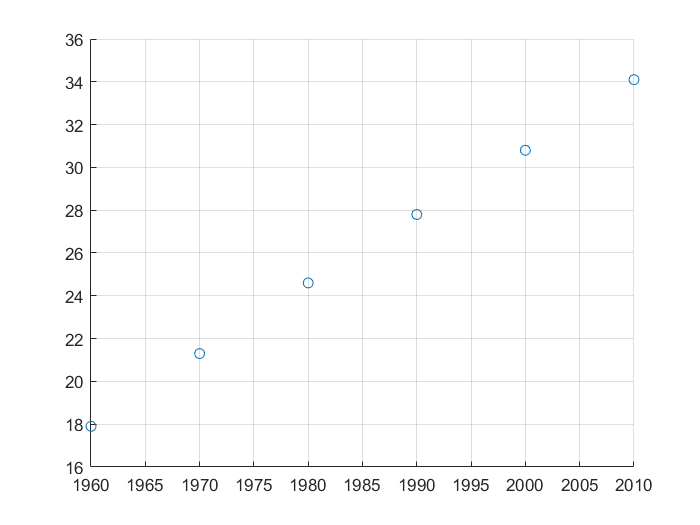

clear all; close all; clc
t_7 = [1960:10:2010];
p_7 = [17.9, 21.3, 24.6, 27.8, 30.8, 34.1];
scatter(t_7, p_7);
grid on

h_7 = 10;
df_7_2010 = (3*p_7(6)-4*p_7(5)+p_7(4))/(2*h_7)

df_7_2010 =    0.345000000000000


三点反向差分公式得到2010年人口增长率为0.345

（2）

$P'(2010)=\frac{P(2020)-P(2000)}{20}$反推$P'(2020)$的人口数

pred_2020 = p_7(5) + 20*df_7_2010

pred_2020 =   37.700000000000010


则预测2020年的结果为37.7百万人。

********************************************function*************************************************

TrapComp：组合梯形公式

function I = TrapComp(f,a,b,n)
%
% TrapComp estimates the value of the integral of f(x)
% from a to b by using the composite trapezoidal rule
% applied to n equal-length subintervals.
%
% I = TrapComp(f,a,b,n) where
%
% f is an inline function representing the integrand,
% a and b are the limits of integration,
% n is the number of equal-length subintervals in [a,b],
%
% I is the integral estimate.
%
% Ramin S. Esfandiari, Numerical Methods for Engineers and Scientists Using
% Matlab,
% Section 6.3.4, p.291
%
h = (b - a)/n;
x = a:h:b;
I = h * (f(a)/2. + sum(f(x(2:n))) + f(b)/2);
end

djp：求解勒让德多项式的零点

function x=jp(N,alpha,beta)

    n=1:N;

    a(1)=(alpha+beta+2)/2;

    b(1)=(beta-alpha)/2;

    a([2:N+1])=(2*n+alpha+beta+1).*(2*n+alpha+beta+2)./(2*(n+1).*(n+alpha+beta+1));

    b([2:N+1])=(alpha*alpha-beta*beta)*(2*n+alpha+beta+1)./(2*(n+1).*(n+alpha+beta+1).*(2*n+alpha+beta));

    c=(n+alpha).*(n+beta).*(2*n+alpha+beta+2)./((n+1).*(n+alpha+beta+1).*(2*n+alpha+beta));

    A=diag(b./a)+diag(1./a([1:N]),1)+diag(c./a([2:N+1]),-1);

    x=sort(eig(A))';
end

function x=djp(N,alpha,beta,m)

    N1=N-m;

    alpha1=alpha+m;

    beta1=beta+m;

    x=jp(N1,alpha1,beta1);
end

GaussL：使用勒让德多项式作为高斯积分的取点

function [I, root, weight] = GaussL(f, a, b, n)
    root = djp(n-1, 0, 0, 0); % 计算n次勒让德多项式的零点
    % 求解高斯积分的权重
    pow = [0:n-1]';
    A = root.^pow;
    B = zeros(n, 1);
    for i = 1:n
        func = @(x) (x.^(i-1));
        B(i) = integral(func, -1, 1);
    end
    weight = A\B;
    x = (b - a)/2*root + (b + a)/2;
    I = (b - a)/2*f(x)*weight;
end